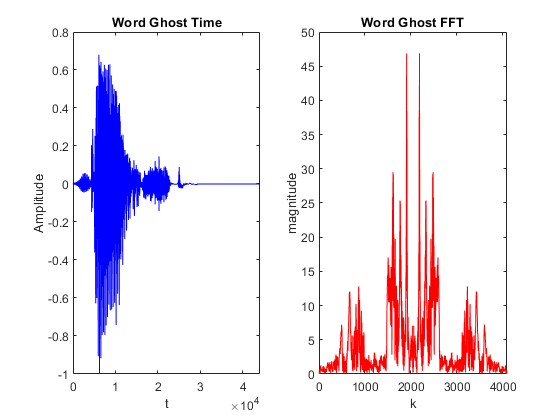

N = 2^12;
phonemes = MakePhenomes(N, true);
wordName = "Ghost";
fileName = "Words\Ghost.mp3";
[wordTime, wordFreq] = MakeWordFromSample(wordName,fileName,N,false);

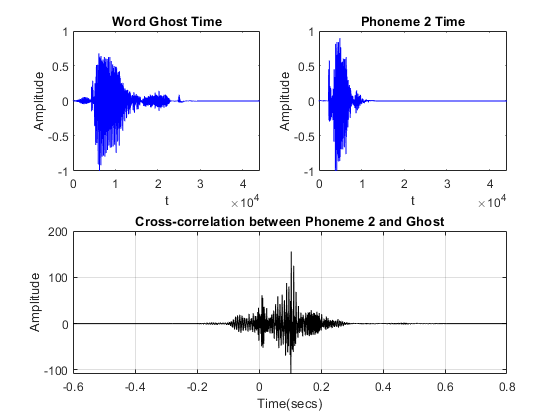

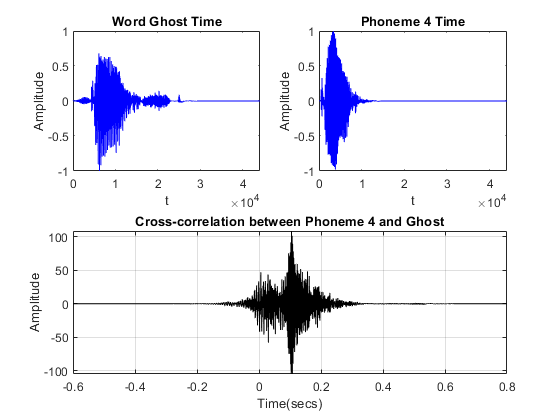

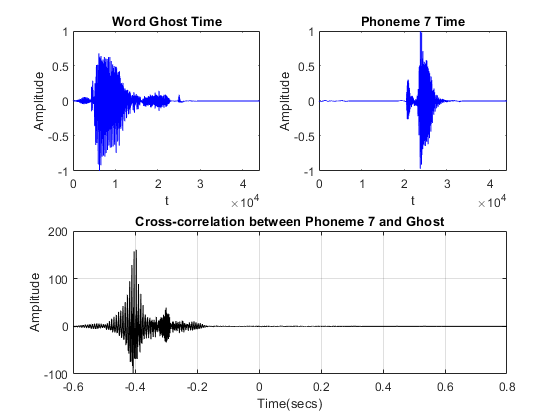

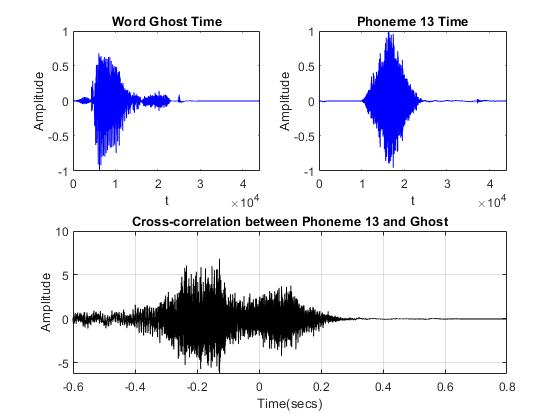

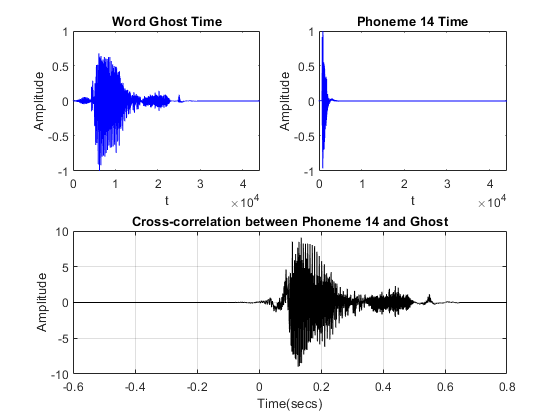

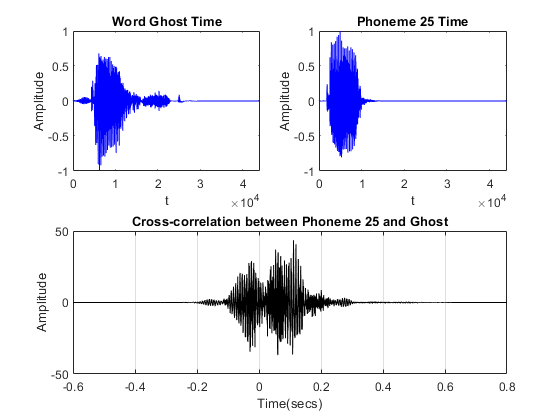

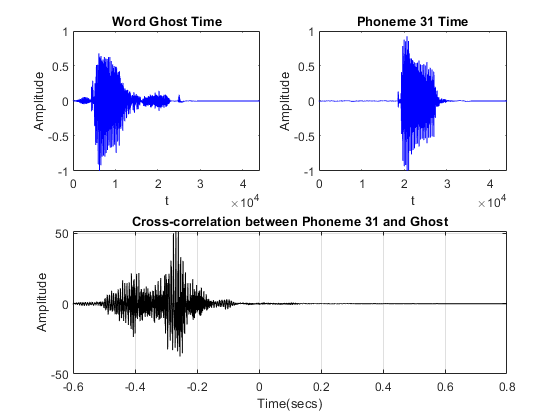

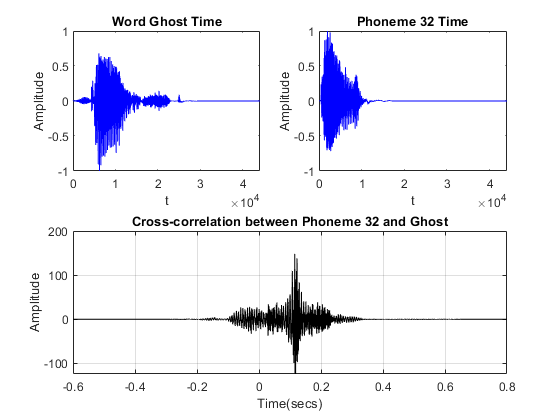

%{

    Time Based Cross Correlation:

    Advantages:
        - Works great for Vowel Identification, as most vowels come from
        the lungs and lips. The intensity of air being blown out of the
        mouth is a good indicator for the vowel since each vowel phoneme
        requires a different breath type and strength.

    Disadvantages:
        - Has trouble identifying consonant of sounds due to the wide array
        of how sounds are made from the mouth for consonants.
        - Phoneme 13: "s" has a really low correlation despite being in the
        word "Ghost"
        - Phoneme 2: "d" has a really high correlation despite being not
        being the word "Ghost" (likely due to the "t"?)

%}
for i = 1:length(phonemes)
    [C1,lag1] = xcorr(wordTime,phonemes(i).Time);       
    
    figure
    subplot(2,2,1);
    plot(wordTime, '-b');
    xlabel('t');
    ylabel('Amplitude');
    title("Word "+wordName+" Time");
    
    subplot(2,2,2);
    plot(phonemes(i).Time, '-b');
    xlabel('t');
    ylabel('Amplitude');
    title("Phoneme "+phonemes(i).ID+" Time");

    
    ax(1) = subplot(2,2,[3,4]); 
    plot(lag1/fs,C1,'k')
    ylabel('Amplitude')
    grid on
    title("Cross-correlation between Phoneme "+phonemes(i).ID+" and "+wordName);
    xlabel('Time(secs)')
    xlim([-0.6, 0.8])
end

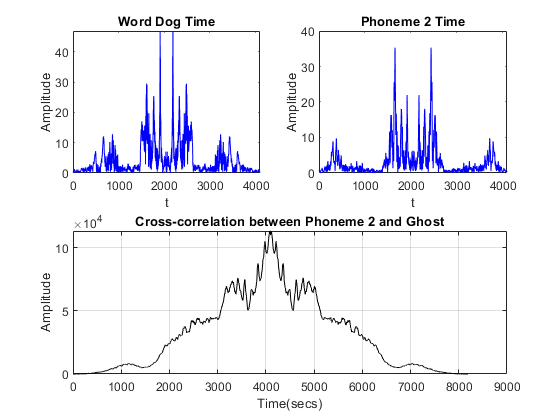

corrArea = 2.5373e+08

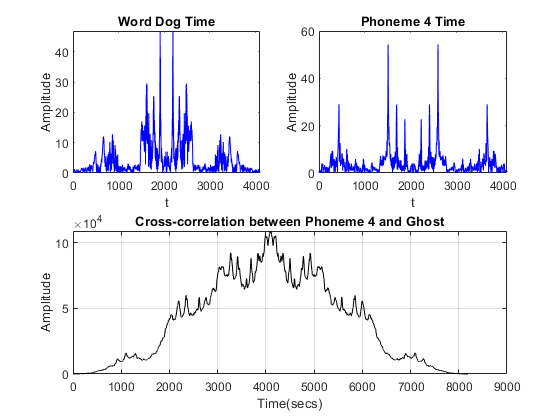

corrArea = 3.2123e+08

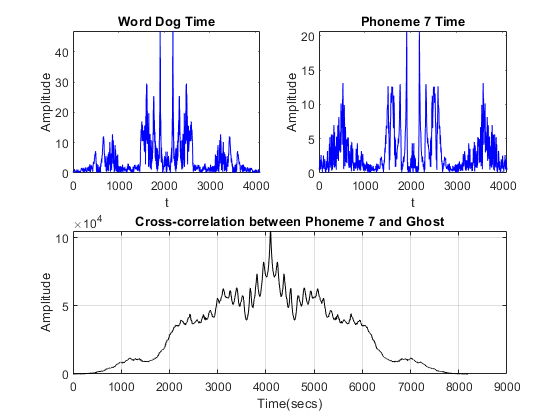

corrArea = 2.3880e+08

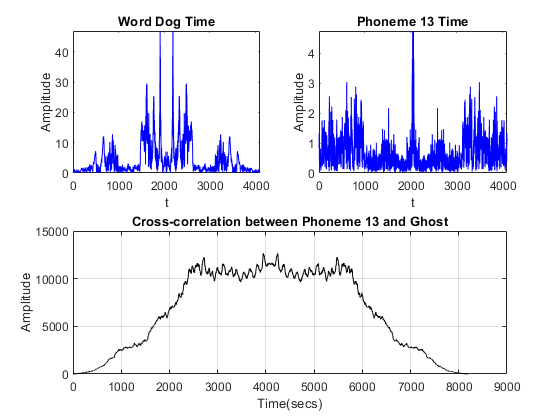

corrArea = 5.3344e+07

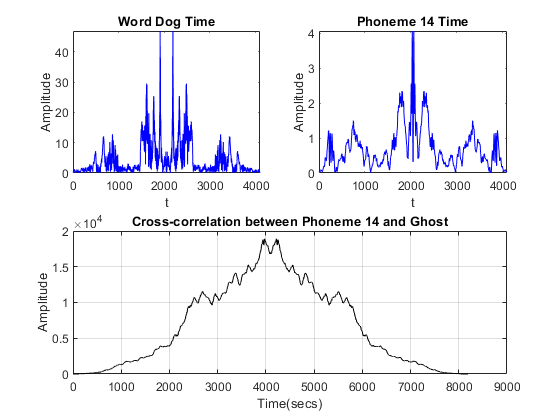

corrArea = 5.4822e+07

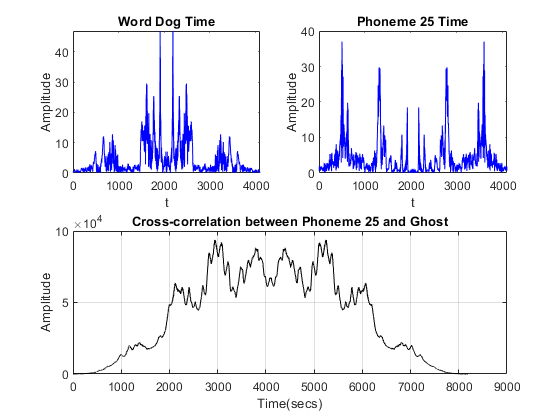

corrArea = 3.3028e+08

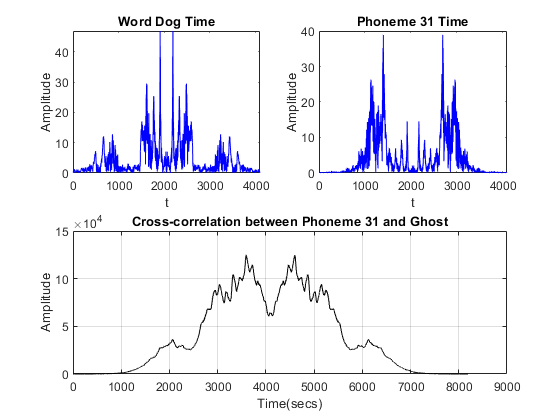

corrArea = 3.1724e+08

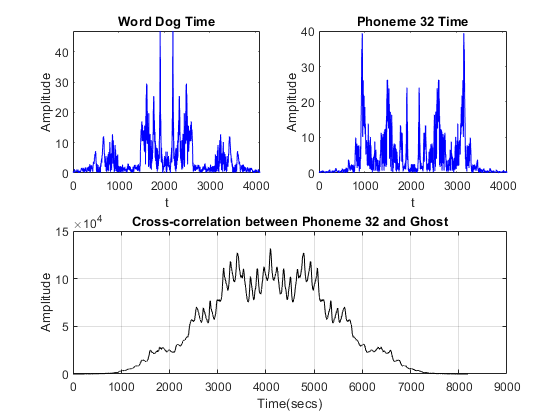

corrArea = 3.4421e+08

for i = 1:length(phonemes)
    C1= xcorr2(wordFreq,phonemes(i).FFT);       
    
    figure
    subplot(2,2,1);
    plot(wordFreq, '-b');
    xlabel('t');
    ylabel('Amplitude');
    title("Word "+"Dog"+" Time");
    
    subplot(2,2,2);
    plot(phonemes(i).FFT, '-b');
    xlabel('t');
    ylabel('Amplitude');
    title("Phoneme "+phonemes(i).ID+" Time");

    
    ax(1) = subplot(2,2,[3,4]); 
    plot(C1,'k')
    ylabel('Amplitude')
    grid on
    title("Cross-correlation between Phoneme "+phonemes(i).ID+" and "+wordName);
    xlabel('Time(secs)')
    
    corrArea = sum(C1)
end

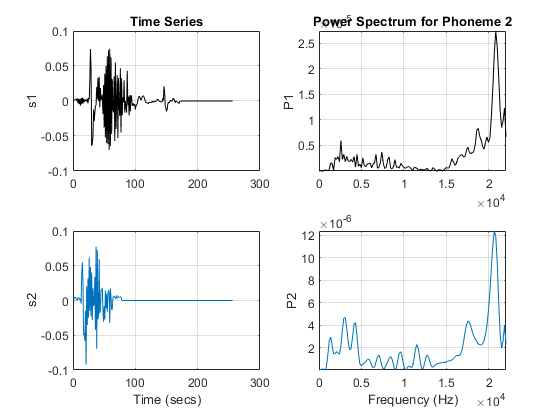

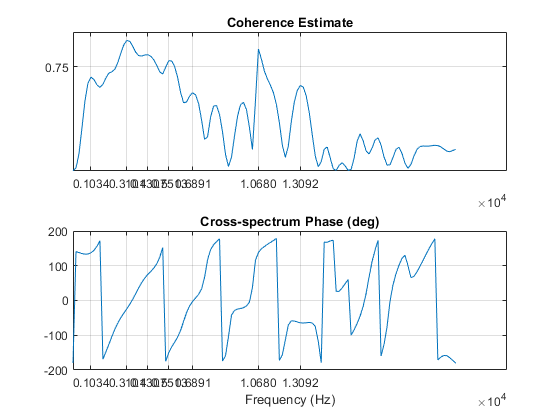

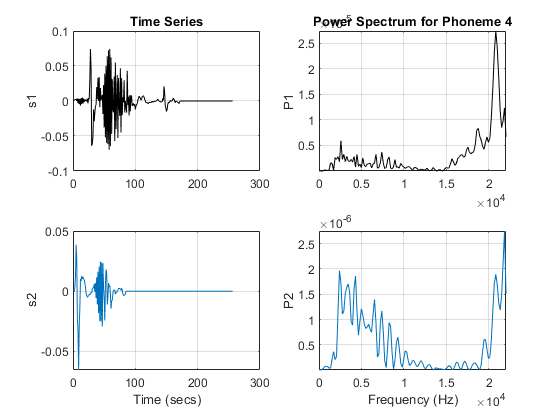

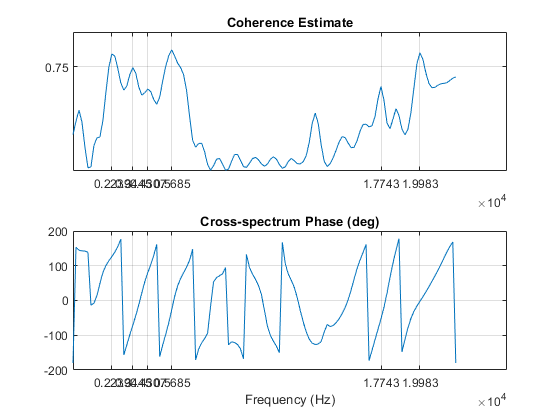

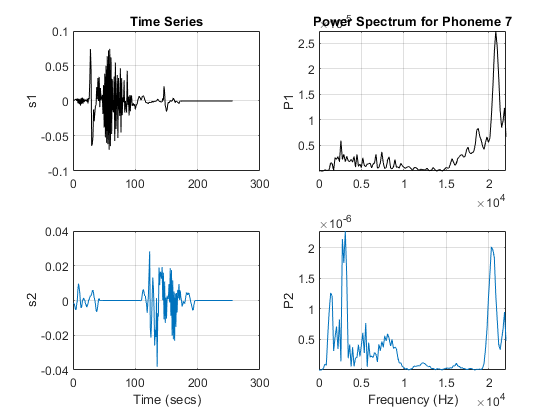

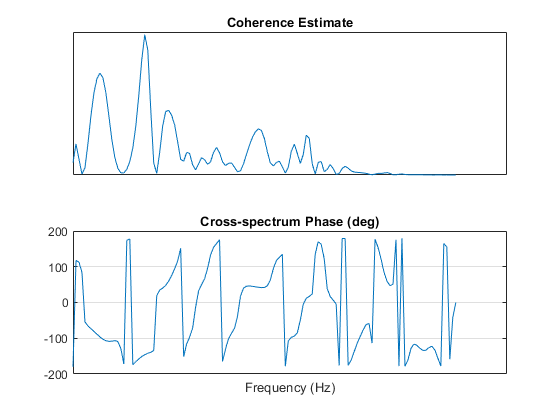

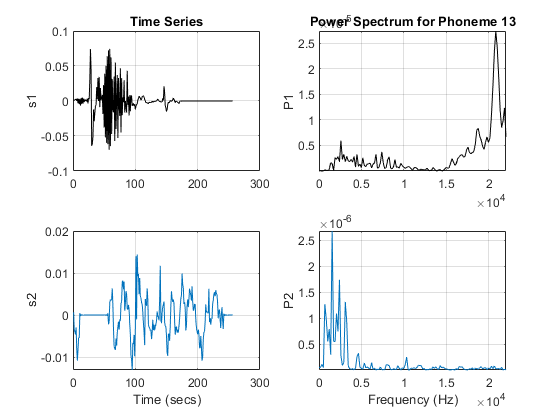

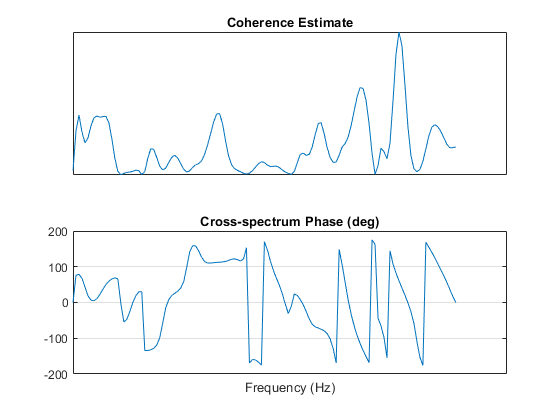

N2 = 2^8;

wordResample = resample(wordTime, N2, length(wordTime));

for i = 1:length(phonemes)
    phonResample = resample(phonemes(i).Time, N2, length(phonemes(i).Time));

    [P1, f1] = periodogram(wordResample,[],[],fs,'power');
    [P2, f2] = periodogram(phonResample,[],[],fs,'power');
    
    figure
    subplot(2,2,1)
    plot(wordResample,'k')
    ylabel('s1')
    grid on
    title('Time Series')
    subplot(2,2,3)
    plot(phonResample)
    ylabel('s2')
    grid on
    xlabel('Time (secs)')
    subplot(2,2,2)
    plot(f1,P1,'k')
    ylabel('P1')
    grid on
    axis tight
    title("Power Spectrum for Phoneme "+phonemes(i).ID)
    subplot(2,2,4)
    plot(f2,P2)
    ylabel('P2')
    grid on
    axis tight
    xlabel('Frequency (Hz)')
    
    [Cxy,f] = mscohere(wordResample,phonResample,[],[],[],fs);
    Pxy = cpsd(wordResample,phonResample,[],[],[],fs);
    phase = -angle(Pxy)/pi*180;
    
    [pks,locs] = findpeaks(Cxy,'MinPeakHeight',0.5);
    
    figure
    subplot(2,1,1)
    plot(f,Cxy)
    title('Coherence Estimate')
    grid on
    hgca = gca;
    hgca.XTick = f(locs);
    hgca.YTick = 0.75;
    subplot(2,1,2)
    plot(f,phase)
    title('Cross-spectrum Phase (deg)')
    grid on
    hgca = gca;
    hgca.XTick = f(locs);
    xlabel('Frequency (Hz)')
end